## **Generate All Features**

clear;
clc;
close all;
rng(0,"twister"); % set random seed for reproducibility
numSamples = 1000;

% generate random income data (median income of the area of house)
% however, lets have it be known that income itself will 
% be exponenetial (you tend to start making BANK when you make bank)
% user will then go through and examine individual features
minIncome = 1;
maxIncome = 20;
income = (maxIncome-minIncome).*rand(numSamples,1) + minIncome;
income = exp(income);

% generate random bedroom data (number of beds in the house
minBedroom = 1;
maxBedroom = 20;
bedrooms = (maxBedroom-minBedroom).*rand(numSamples,1) + minBedroom;

% generate population data (population of the surrounding neighborhood)
minPopulation = 100;
maxPopulation = 2000;
population = (maxPopulation - minPopulation).*rand(numSamples,1) + minPopulation;

% generate family data (number of people living in each house)
minFamilySize = 1;
maxFamilySize = 20;
sizeFamily = (maxFamilySize - minFamilySize).*rand(numSamples,1) + minFamilySize;


## Create Response Variable

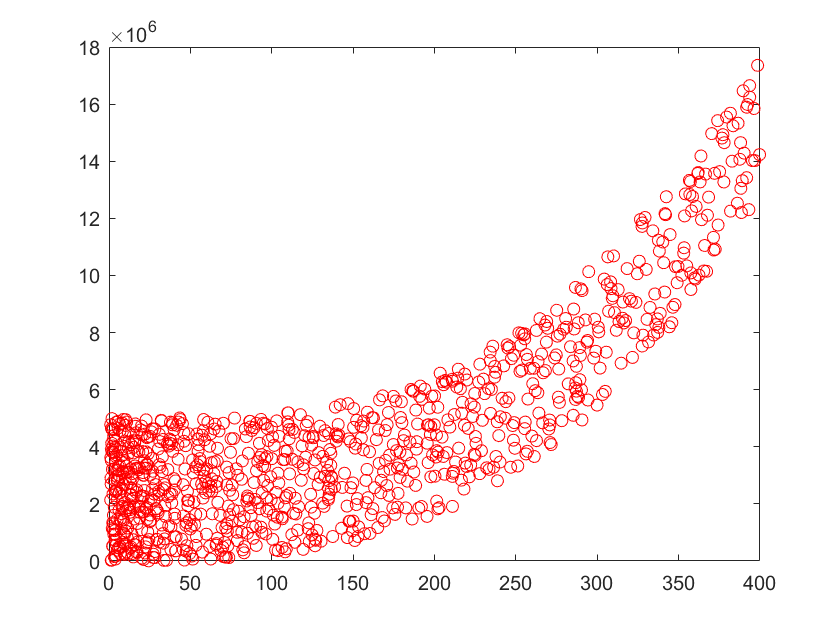

% the "real" relationship will be a combination of family size and nearby
% population
% keep the indexes for mapping these for later
[sortedIncome, idxIncome] = sort(income);
[sortedFamily, idxFamily] = sort(sizeFamily);


% create the "equation" for the response variable
randomConstant = 5;
masterFeature = log(sortedIncome).* sortedFamily;
housePrice = 0.2*masterFeature.^3 + 0.3*masterFeature.^2 + 1.7* masterFeature + randomConstant;

%peturb the y values as much by up to 10
perturbs =  5000000*rand(length(income),1) + 1;
r = randperm(length(income));
%perturbs(r(1:floor(0.5*length(income)))) = -1 * perturbs(r(1:floor(0.5*length(income))));

housePrice = perturbs + housePrice;
plot(masterFeature,housePrice, 'ro')

## **Save Variables For Future Use**

% bring all the observations together
% important variables are income, family size, and housePrice
shuffleOrder = randperm(length(housePrice));
income = sortedIncome(shuffleOrder);
sizeFamily = sortedFamily(shuffleOrder);
housePrice = housePrice(shuffleOrder);

% create a table
housingData = table(income, sizeFamily, bedrooms, population, housePrice);
save('housingData', 'housingData')